# Heat Transfer in a Pipe 

## Create the thermal model 

type = 'thermal';
model = createpde(type);

## Create the geometry

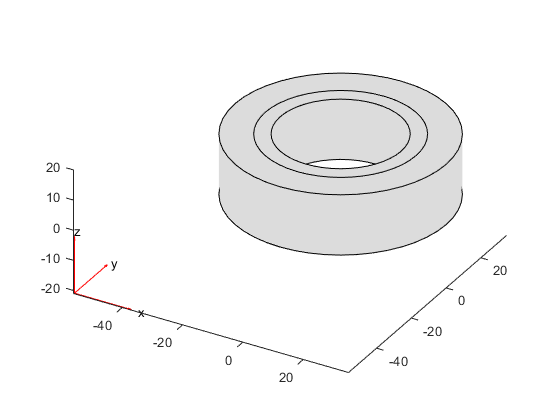

geom = multicylinder([20,25,35],20,'Void',[1,0,0]);
model.Geometry = geom;
pdegplot(model);

## Mesh the model

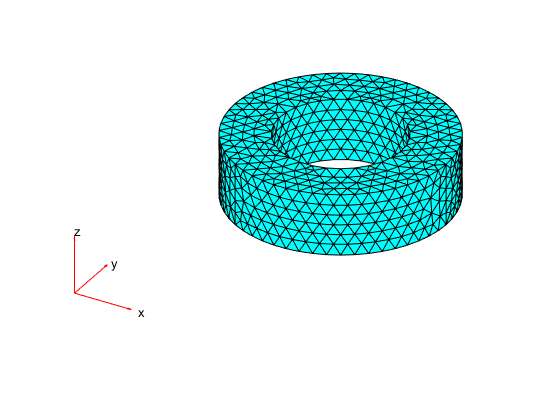

generateMesh(model);
pdemesh(model);

# Explore Heat Transfer in a Multidomain Pipe

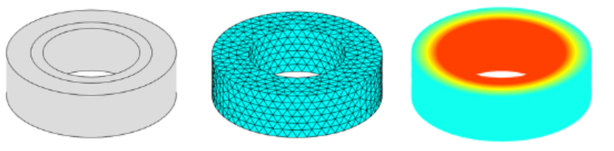

## Finite Element Analysis Workflows in MATLAB

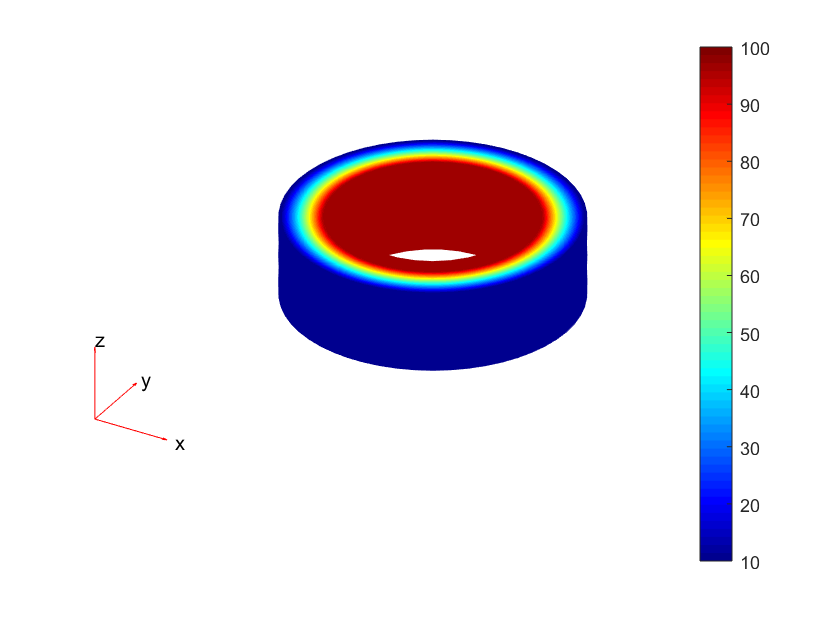

T1 =96;
T2 = 6;
thermalProperties(model,'cell',1,'ThermalConductivity',40);
thermalProperties(model,'cell',2,'ThermalConductivity',0.15);
thermalBC(model,'Face',3,'Temperature',T1);
thermalBC(model,'Face',7,'Temperature',T2);
results = solve(model);
pdeplot3D(model,'ColorMapData',results.Temperature)
caxis([10 100])